%% Q1 Using MATLAB, generate a matrix called pn that encodes the 4 patterns on slide 35 as a 4 by 8 matrix with values -1 and +1.
% data obtained on slide 51
pn = [1 1 -1 -1 -1 -1 -1 1;
    -1 1 1 1 -1 -1 1 -1;
    -1 -1 1 1 1 -1 -1 -1;
    1 -1 -1 1 -1 1 -1 1];

%% Q2  Call the function w = memstor(pn) to create a Hopfield network (an 8x8 matrix) from the patterns.  (memstor is on slide 54).
w = memstor(pn)

w =      0     0    -4    -2    -2     2    -2     4
     0     0     0    -2    -2    -2     2     0
    -4     0     0     2     2    -2     2    -4
    -2    -2     2     0     0     0     0    -2
    -2    -2     2     0     0     0     0    -2
     2    -2    -2     0     0     0     0     2
    -2     2     2     0     0     0     0    -2
     4     0    -4    -2    -2     2    -2     0



%% Q3 Compute the Goodness Value for for all possible patterns (goodness.m is in the slide set).
g = goodness(w)

ans =     -1    -1    -1    -1    -1    -1    -1    -1   -12
     1    -1    -1    -1    -1    -1    -1    -1    -4
    -1     1    -1    -1    -1    -1    -1    -1    -4
     1     1    -1    -1    -1    -1    -1    -1     4
    -1    -1     1    -1    -1    -1    -1    -1    -4
     1    -1     1    -1    -1    -1    -1    -1   -12
    -1     1     1    -1    -1    -1    -1    -1     4
     1     1     1    -1    -1    -1    -1    -1    -4
    -1    -1    -1     1    -1    -1    -1    -1    -4
     1    -1    -1     1    -1    -1    -1    -1    -4


g =    -12
    -4
    -4
     4
    -4
   -12
     4
    -4
    -4
    -4


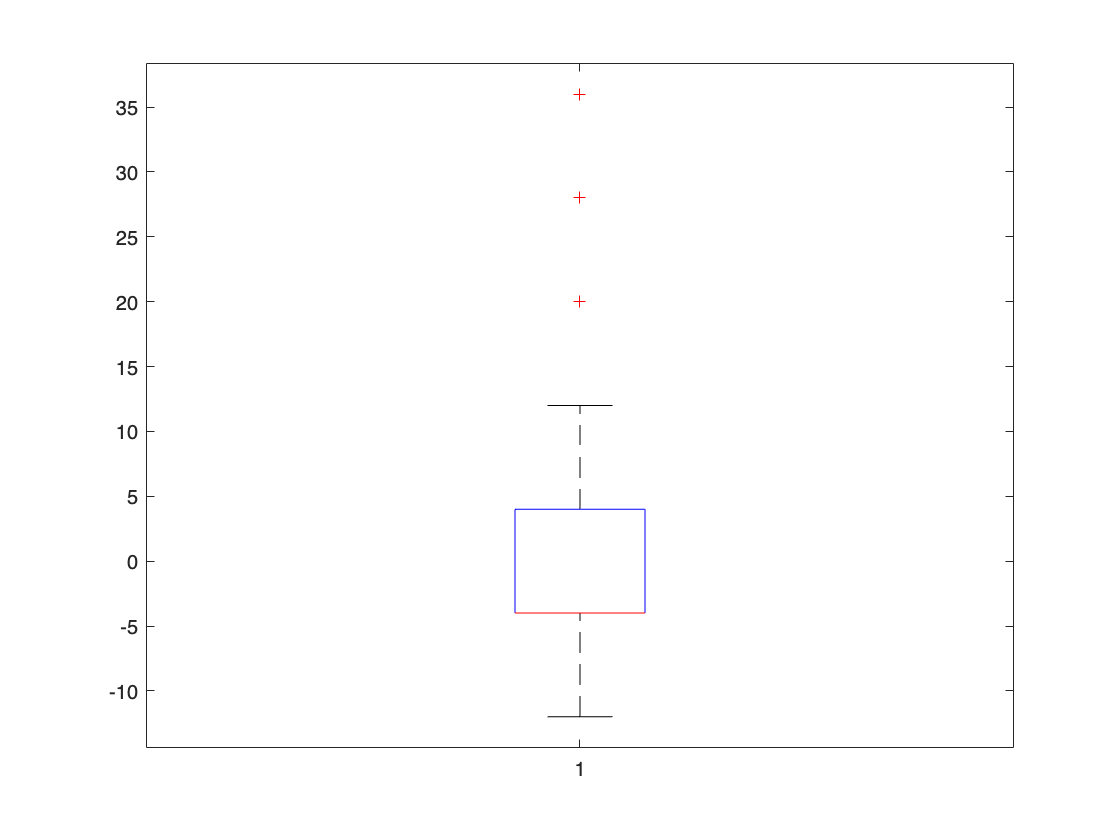


%% Q4 Generate a boxplot or histogram that shows the distribution of Goodness values across all 2^8 binary patterns ( components are -1 or +1)
figure
boxplot(g)

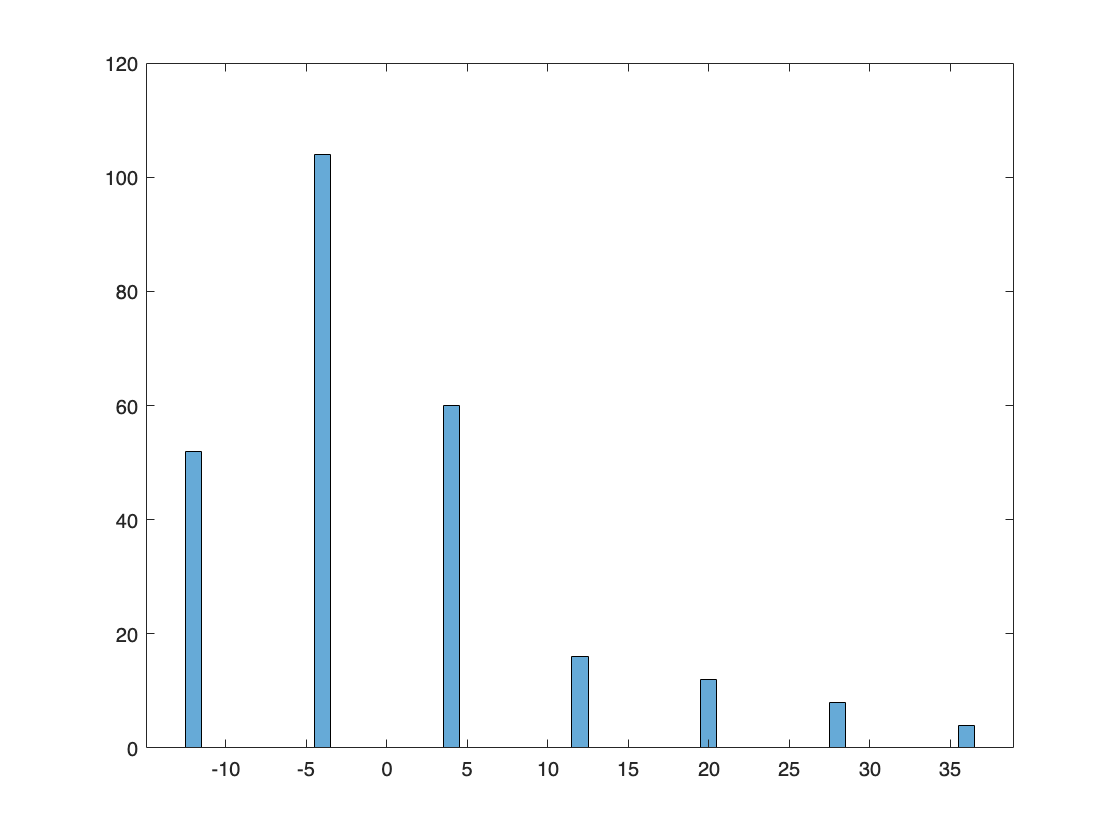

figure
histogram(g)


%% Q5 Using hopupdate.m and the Necker cube weights (both from the slide set), run a Hopfield net for many iterations and interpret the result.  (show a printout of the final activities -- a plot is great, just numbers is sufficient)
clear;
% Necker cube obtained from slide 17
w=[0.0  1.0  1.0  0.0  1.0  0.0  0.0  0.0 -1.5  0.0 -1.5  0.0  0.0  0.0  0.0  0.0;
    1.0  0.0  0.0  1.0  0.0  1.0  0.0  0.0  0.0 -1.5  0.0 -1.5  0.0  0.0  0.0  0.0;
    1.0  0.0  0.0  1.0  0.0  0.0  1.0  0.0 -1.5  0.0 -1.5  0.0  0.0  0.0  0.0  0.0;
    0.0  1.0  1.0  0.0  0.0  0.0  0.0  1.0  0.0 -1.5  0.0 -1.5  0.0  0.0  0.0  0.0;
    1.0  0.0  0.0  0.0  0.0  1.0  1.0  0.0  0.0  0.0  0.0  0.0 -1.5  0.0 -1.5  0.0;
    0.0  1.0  0.0  0.0  1.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0 -1.5  0.0 -1.5;
    0.0  0.0  1.0  0.0  1.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0 -1.5  0.0 -1.5  0.0;
    0.0  0.0  0.0  1.0  0.0  1.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0 -1.5  0.0 -1.5;
    -1.5  0.0 -1.5  0.0  0.0  0.0  0.0  0.0  0.0  1.0  1.0  0.0  1.0  0.0  0.0  0.0;
    0.0 -1.5  0.0 -1.5  0.0  0.0  0.0  0.0  1.0  0.0  0.0  1.0  0.0  1.0  0.0  0.0;
    -1.5  0.0 -1.5  0.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  1.0  0.0  0.0  1.0  0.0;
    0.0 -1.5  0.0 -1.5  0.0  0.0  0.0  0.0  0.0  1.0  1.0  0.0  0.0  0.0  0.0  1.0;
    0.0  0.0  0.0  0.0 -1.5  0.0 -1.5  0.0  1.0  0.0  0.0  0.0  0.0  1.0  1.0  0.0;
    0.0  0.0  0.0  0.0  0.0 -1.5  0.0 -1.5  0.0  1.0  0.0  0.0  1.0  0.0  0.0  1.0;
    0.0  0.0  0.0  0.0 -1.5  0.0 -1.5  0.0  0.0  0.0  1.0  0.0  1.0  0.0  0.0  1.0;
    0.0  0.0  0.0  0.0  0.0 -1.5  0.0 -1.5  0.0  0.0  0.0  1.0  0.0  1.0  1.0  0.0];

iv = (rand(16,1)>0.5)*2-1 % generate a initial value of a random matrix of [-1, 1]

iv =      1
     1
    -1
     1
     1
    -1
    -1
     1
     1
     1


h = hopupdate(w,iv,100)

h =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1


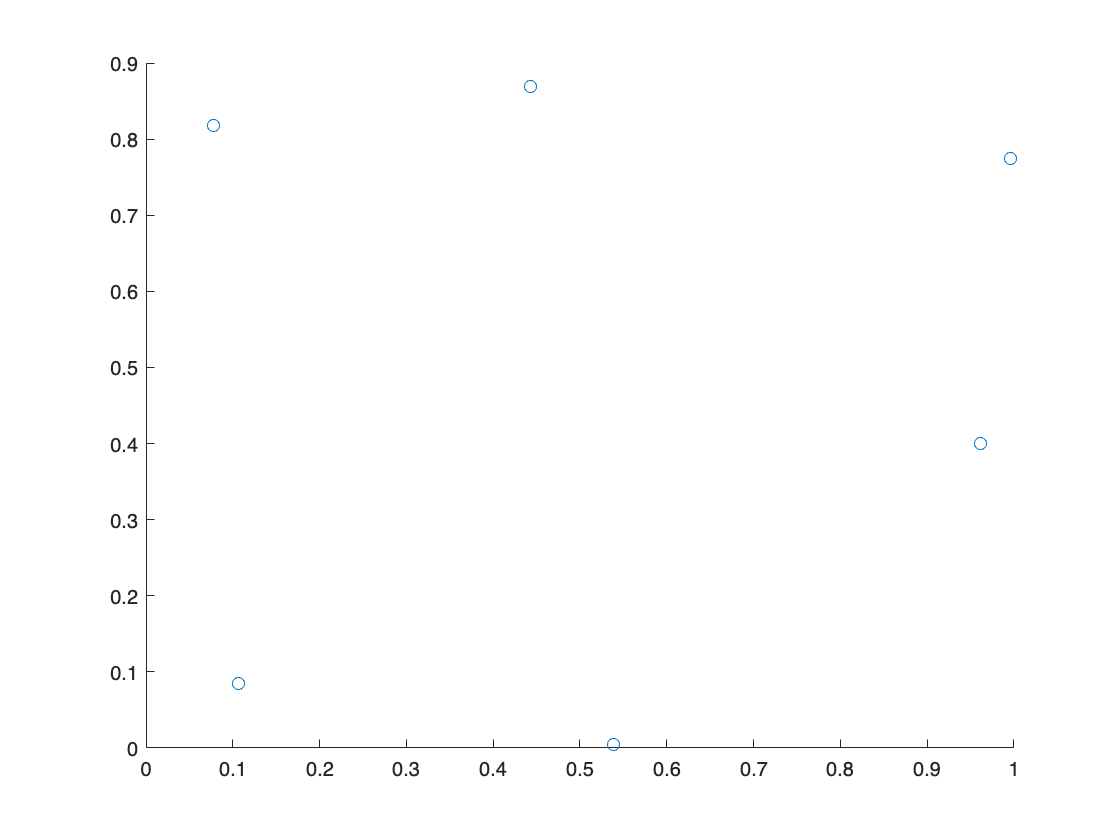


%% Q6 Replicate the TSP example from the slides using a set of 6 random cities (instead of 7)
locations=rand(6,2); %creates 6 random locations
scatter(locations(:,1),locations(:,2));

dmat=squareform(pdist(locations)); %computes the distance matrix
tspmat=hopfieldwts(6,45,dmat);
iacn(.05*rand(6,6),0.2*rand(6,6),tspmat,.05,100000)

ans =     0.0000    0.0000    0.0000    0.0000    1.0000    0.0000
    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000
    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000



%% Q7  Download the matlab programs in the module.  Try running tsp.m which runs a constraint satisfaction neural network to find a short path.
%{
- tsp.m generates a set of random locations and finds a path through them -- the network does not always converge to a path in which case the program will show an error.
- The user (you) can set the number of locations and the magnitude of the inhibition in the first two lines of tsp.m
- After running it, you can run it subsequent trials to find a different route for the same set of locations by commenting out line 4.  If you don't comment out line 4 -- a new set of random locations will be generated.
- If the programs does not converge on several trials, try increasing the "inhib" parameter (line 2).  If it is too high, the routes will get less optimal. %}
%}
clear;
% We'll need those .m files provided by professor to run below
tsp;

Unrecognized function or variable 'tsp'.


%% Attachments
% scraped from lecture slides

function mem=memstor(pats)
% each row of the matrix pats is a pattern
[np nd]= size(pats) ;
mem=zeros(nd) ;
for i=1:nd
    for j=1:nd
        if (i~=j)
            for k=1:np
                mem(i,j)=mem(i,j)+pats(k,i)*pats(k,j) ;
            end
        end
    end
end
end


function gvals = goodness( hopnet )
%calculates goodness for all patterns in a Hopfield Network
gvals=[];
pmat=[] ;
netsize=size(hopnet,1) ;
for k=0:(2^netsize-1)
    pvec=2*de2bi(k,netsize)-1; % need package
    %pvec=pvec([end:-1:1]) ;
    pmat=[pmat;pvec];
    g=0;
    for i=1:(netsize-1)
        for j=(i+1):netsize
            g=g+hopnet(i,j)*pvec(i)*pvec(j) ;
        end
    end
    gvals=[gvals, g];

end
gvals=gvals';
[pmat,gvals]
end

function hmtx=hopfieldwts(nc,mag,distances)
% nc = number of cities
% mag = magnitude of constraint (usually between 10 and 50)
% matrix is [target (city, position), source (target, position) ]
hmtx=zeros(nc,nc,nc,nc) ;
mdist=max(max(distances)) ;
nsd=10.0 ;
revdist=10*(mdist-distances+1).*(mdist-distances+1)/(mdist*mdist) ;
%revdist=0.1+10*exp(-distances.*distances/(mdist*mdist/(nsd*nsd))) ;
%revdist=0.1./(0.1+distances.*distances) ;
for j=1:nc
    hmtx(j,:,j,:)=mag*(eye(nc)-1) ;
    hmtx(:,j,:,j)=mag*(eye(nc)-1) ;
end
for j=2:nc
    for k=1:(j-1)
        % for each distance in the matrix distances
        for m1=1:nc
            m2=1+mod(m1,nc) ;
            hmtx(j,m1,k,m2) = revdist(j,k) ;
            hmtx(k,m1,j,m2) = revdist(j,k) ;
            hmtx(j,m2,k,m1) = revdist(j,k) ;
            hmtx(k,m2,j,m1) = revdist(j,k) ;
        end
    end
end
end

function finalact=iacn(extin,initact,conmat,dt,niter)
finalact=initact;
for k=1:niter
    finalact=iaciter(extin,finalact,conmat,dt);
end
end

function newact=iaciter(extinp,oldact,cmat,lr)
% Interactive activation model
% extinp -- ext input to each node
% oldact -- prev activity matrix (courses,times)
% cmat is the constraint matrix
% newact is the activity after a single iteration
% lr is the learning rate -- MUST BE < 1
del=mul4d2d(cmat,oldact) + extinp ; % netinputs to each hypothesis node
ldel = 2./exp(-del) - 1.0 ; % squashes input to [-1 +1]
newact = oldact + lr*(ldel>0).*(1-oldact) - lr*(ldel<0).*oldact ;
end

function outm=mul4d2d(m4d,m2d)
newdim=prod(size(m2d));
m4d2=reshape(m4d,newdim,newdim) ;
m2d1=reshape(m2d,newdim,1);
penout=m4d2*m2d1 ;
outm=reshape(penout,size(m2d)) ;
end

function newact = hopupdate( hmat,oldact,niter )
% hopfield updates for a fixed number of iterations
% (not the traditional stopping criterion)
newact=oldact ;
for ii=1:niter
    rrownum=randi(size(hmat,1),1); % fixed irand()
    if (hmat(rrownum,:).*newact'>0)
        newact(rrownum)=1 ;
    else
        newact(rrownum)=-1;
    end
end
end